Amb aquest programa podem carregar una imatge i ens retornara el valor numeric del digit present en la imatge. 

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 2, 48000);
load('model.mat');
im = ims(:,:,1);

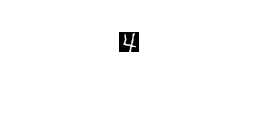

imshow(im)

prediction = classify(im)

imb = imbinarize(im);
%Area
areas = bwarea(imb);
convexArea = bwarea(imbinarize(imsubtract(bwconvhull(imb), imb)));
%Transformada de Hough
longLines = houghTransform(im);
hough = [longLines.point1, longLines.point2, longLines.theta, longLines.rho];

%Orientació
orientationHist = extractHOGFeatures(imb, 'CellSize',[4,4]);
t = table(areas, convexArea, orientationHist, hough);


model = trainedModel.ClassificationSVM;
label = predict(model, t);

Error using classreg.learning.internal.table2PredictMatrix>makeXMatrix (line 75)
Missing value for predictor orientationHist_1.

Error in classreg.learning.internal.table2PredictMatrix (